# TP2 - MAT6473

format compact;
format long e;

## Question 1

Le système d'edos initial pour la trajectoire du satellite est 


$$\frac{d^2x}{dt^2} = x+ 2\frac{dy}{dt} - (1-\mu)\left(\frac{x+\mu}{((x+\mu)^2 +y^2)^{3/2}}\right)-\mu\left(\frac{x-1+\mu}{((x-1+\mu)^2 +y^2)^{3/2}}\right)\\
\frac{d^2y}{dt^2} = y- 2\frac{dx}{dt} - (1-\mu)\left(\frac{y}{((x+\mu)^2 +y^2)^{3/2}}\right)-\mu\left(\frac{y}{((x-1+\mu)^2 +y^2)^{3/2}}\right)$$


où $\mu := m/M \approx 0.012155092$.

En prenant


$$z_1 = x\\
z_2 = y\\
z_3 = \frac{dx}{dt}\\
z_4 = \frac{dy}{dt}.$$


On obtient le système $\hat{z}' = \left(z_1,z_2,z_3,z_4 \right)^T = \hat{f}$


$$z_1' = z_3\\
z_2' = z_4\\
z_3' = z_1+ 2z_4 - (1-\mu)\left(\frac{z_1+\mu}{((z_1+\mu)^2 +z_2^2)^{3/2}}\right)-\mu\left(\frac{z_1-1+\mu}{((z_1-1+\mu)^2 +z_2^2)^{3/2}}\right)\\
z_4' = z_2- 2z_3 - (1-\mu)\left(\frac{z_2}{((z_1+\mu)^2 +z_2^2)^{3/2}}\right)-\mu\left(\frac{z_2}{((z_1-1+\mu)^2 +z_2^2)^{3/2}}\right)$$
    

avec les conditions initiales suivantes


$$(i) \ \ z_1(0) = -2.499999883 ; \  \  z_2(0) = 0 ; \  \ z_3(0) = 0; \ z_4(0) = 2.100046263\\
(ii) \ \ z_1(0) =0.952281734; \  \  z_2(0) = 0 ; \  \ z_3(0) = 0; \ z_4(0) = -0.957747254\\
(iii) \ \ z_1(0) = 3.147603117 ; \  \  z_2(0) = 0 ; \  \ z_3(0) = 0; \ z_4(0) = -3.07676285
$$


## Question 2

Fixons la tolérance sur la précision à $1\times {10}^{-6}$ pour calculer la période du satellite $T$ avec les différentes conditions initiales en utilisant Runge-Kutta-Fehlberg (RKF).

tol = 1e-6;
tolPeriode = 1e-6;
mu = 0.012155092;

dFinRKF = zeros(3,1);   % Distance entre point finale et intiale avec RKF
dFinRK4 = zeros(3,1);   % Distance entre point finale et intiale avec RK4

### 2.1 Période $T_1$ avec condition initiale (i)

#### (2.1.a) Regardons la trajectoire sur l'intervalle de temps [0,13]. 

intervalle = [0,13];
z0 = [-2.499999883 ;0.0 ;0.0; 2.100046263];
[Z1,~,tList1] = rkf2023(@fTroisCorps,intervalle,z0,tolPeriode);

Graphique de la trajectoire

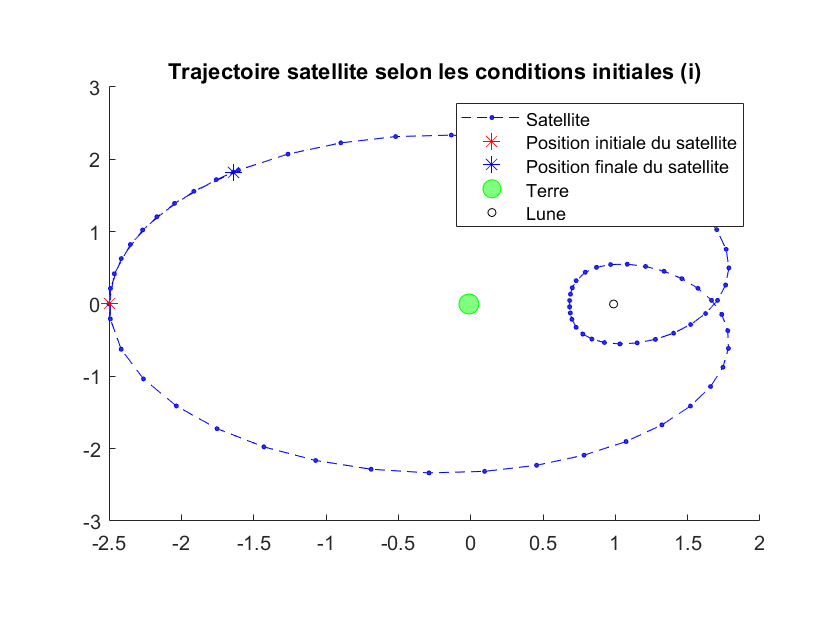

figure(1);
clf;
hold on;
plot(Z1(1,:),Z1(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z1(1,end),Z1(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Terre','Lune','Location',"northeast")
title('Trajectoire satellite selon les conditions initiales (i)')
pbaspect([6 4 1])

#### (2.1.b) Trouver la période $T_1$

Z=Z1;      % Adapté selon la situation

listI = [0;0];      % Liste de l'index et du temps de partage
cand = z0;          % Liste de candidats passant par l'axe des x
candDist = z0-z0;   % Distance avec conditions initiales

for i=3:length(Z)
    yp = Z(2,i-1);
    yn = Z(2,i);
    if(yp*yn <= 0)
        % Noter l'index
        listI(:,end+1) = zeros(2,1);
        listI(1,end) = i;
        
        dist = abs(yp)/(abs(yp)+abs(yn));   % Distance par rapport à l'axe des x
        
        % Noter le temps de partage
        listI(2,end) = tList1(i-1) + dist*(tList1(i)-tList1(i-1));
        
        % Créer le candidat sur l'axe
        cand(:,end+1)  = zeros(4,1);
        cand(:,end) = Z1(:,i-1) + dist*(Z(:,i)-Z(:,i-1));
        
        % Distance avec le vecteur de conditions initiales z0
        candDist(:,end+1) = cand(:,end)-z0;
       
    end
end

tolDist = 1e-1;         % Distance toléré avec les conditions initiales
for i =2:length(listI)
    if(norm(candDist(:,i)) < tolDist)
        T1 = listI(2,i)     % Break quand assez proche
        break;
    end
end

T1 =      1.199941763369134e+01

#### (2.1.c) RKF avec le $t_f =T_1$.

intervalle = [0,T1];
z0 = [-2.499999883 ;0.0 ;0.0; 2.100046263];
[Z1,hList1,tList1] = rkf2023(@fTroisCorps,intervalle,z0,tol);
dFinRKF(1) = norm(Z1(:,end)-Z1(:,1));
N1 = length(hList1)

N1 =     67

Graphique de la trajectoire

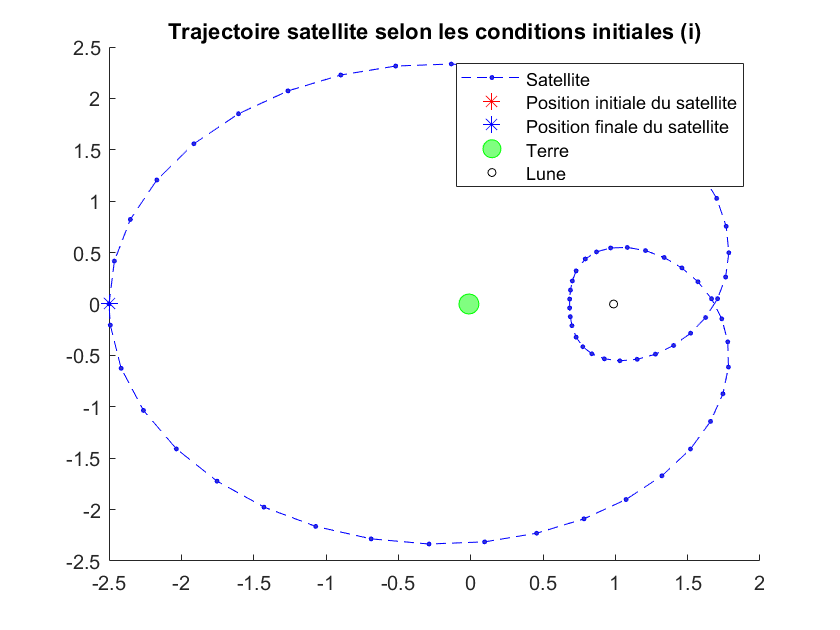

figure(1);
clf;
hold on;
plot(Z1(1,:),Z1(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z1(1,end),Z1(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (i)')

Graphique du pas de temps

plot((1:length(hList1)),hList1,'o--')
xlabel('Itération')
ylabel('Taille du pas h')
title('Pas adaptatif avec les conditions (i)')

### 2.2 Période $T_2$ avec condition initiale (2)

#### (2.2.a) Regardons la trajectoire sur l'intervalle de temps [0,13]. 

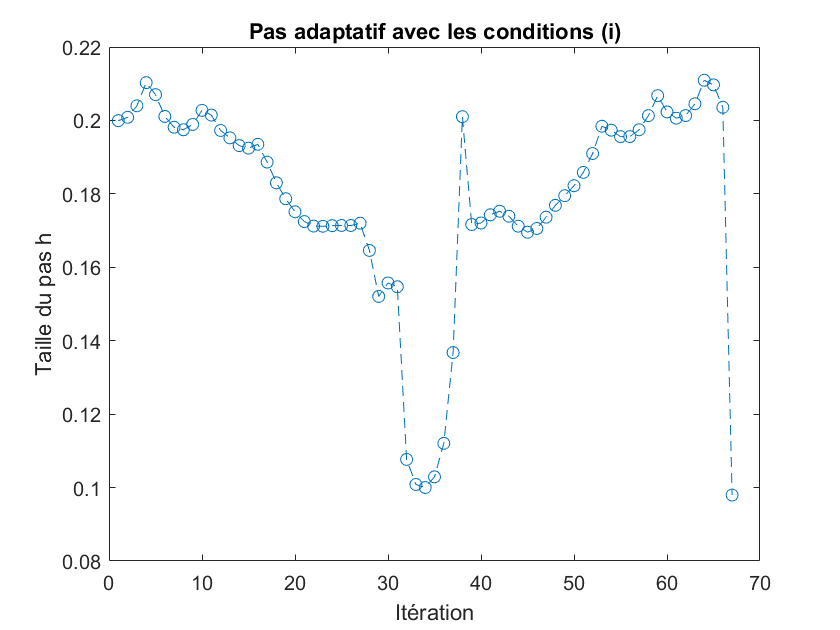

intervalle = [0,13];
z0 = [0.952281734 ;0.0 ;0.0; -0.957747254];

[Z2,~,tList2] = rkf2023(@fTroisCorps,intervalle,z0,tolPeriode);

Graphique de la trajectoire

figure(2);
clf;
hold on;
plot(Z2(1,:),Z2(2,:),'b.-')
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z2(1,end),Z2(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (ii)')

#### (2.2.b) Trouver la période.

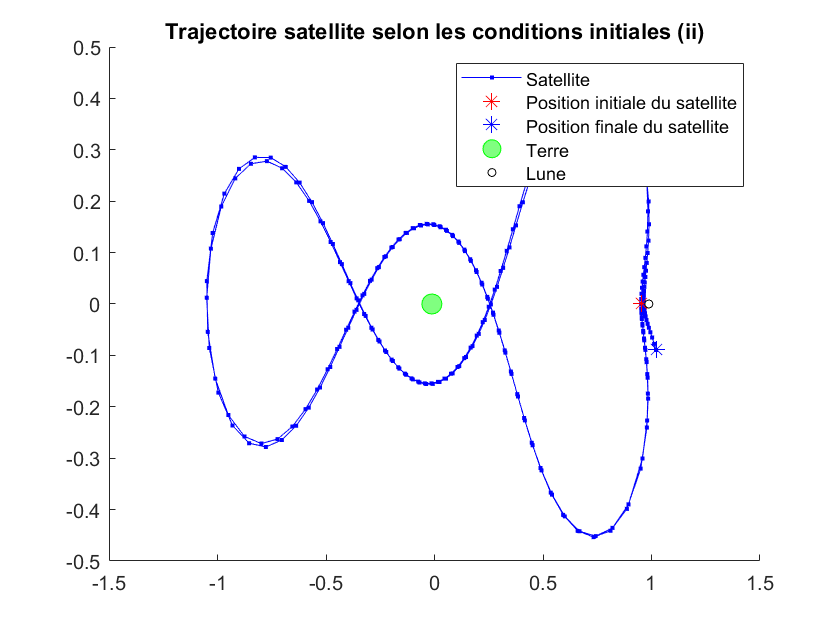

Z=Z2;      % Adapté selon la situation

listI = [0;0];      % Liste de l'index et du temps de partage
cand = z0;          % Liste de candidats passant par l'axe des x

candDist = z0-z0;   % Distance avec conditions initiales

for i=3:length(Z)
    yp = Z(2,i-1);
    yn = Z(2,i);
    if(yp*yn <= 0)
        % Noter l'index
        listI(:,end+1) = zeros(2,1);
        listI(1,end) = i;
        
        dist = abs(yp)/(abs(yp)+abs(yn));   % Distance par rapport à l'axe des x
        
        % Noter le temps de partage
        listI(2,end) = tList2(i-1) + dist*(tList2(i)-tList2(i-1));
        
        % Créer le candidat sur l'axe
        cand(:,end+1)  = zeros(4,1);
        cand(:,end) = Z(:,i-1) + dist*(Z(:,i)-Z(:,i-1));
        
        % Distance avec le vecteur de conditions initiales z0
        candDist(:,end+1) = cand(:,end)-z0;
       
    end
end

tolDist = 1e-1;         % Distance toléré avec les conditions initiales
for i =2:length(listI)
    if(norm(candDist(:,i)) < tolDist)
        T2 = listI(2,i)     % Break quand assez proche
        break;
    end
end

T2 =      6.450488887345917e+00

#### (2.2.c) RKF avec le $t_f =T_2$.

intervalle = [0,T2];
z0 = [0.952281734 ;0.0 ;0.0; -0.957747254];
[Z2,hList2,tList2] = rkf2023(@fTroisCorps,intervalle,z0,tol);
dFinRKF(2) = norm(Z2(:,end)-Z2(:,1));
N2 = length(hList2)

N2 =    120

Graphique de la trajectoire

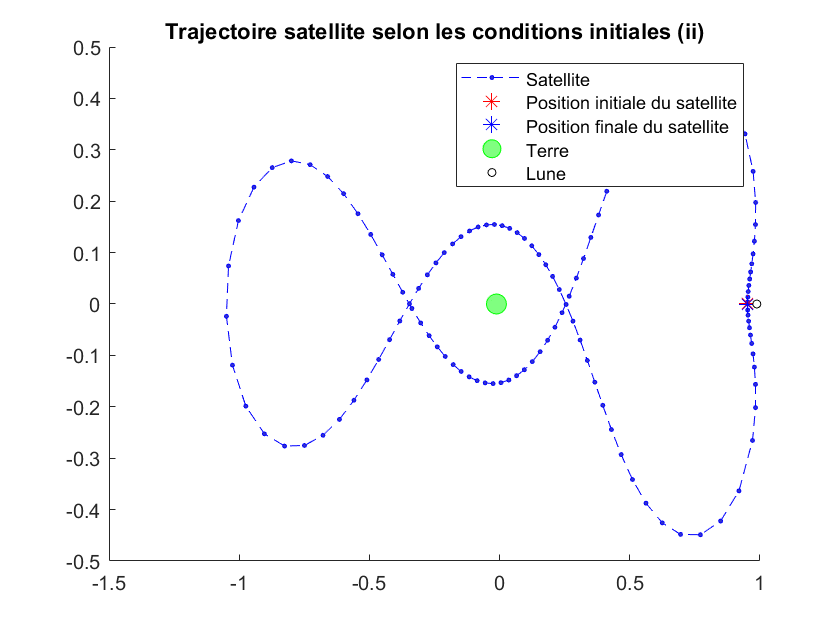

figure(1);
clf;
hold on;
plot(Z2(1,:),Z2(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z2(1,end),Z2(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (ii)')

Graphique du pas de temps

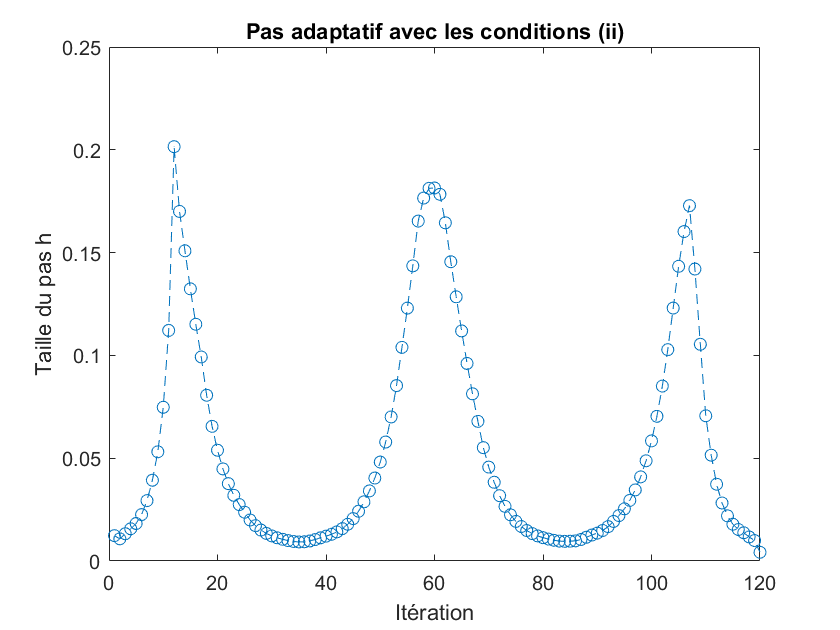

plot((1:length(hList2)),hList2,'o--')
xlabel('Itération')
ylabel('Taille du pas h')
title('Pas adaptatif avec les conditions (ii)')

### 2.3 Période $T_3$ avec condition initiale (3)

#### (2.3.a) Regardons la trajectoire sur l'intervalle de temps [0,13]. 

intervalle = [0,13];
z0 = [3.147603117 ;0.0 ;0.0; -3.07676285];
[Z3,~,tList3] = rkf2023(@fTroisCorps,intervalle,z0,tolPeriode);

Graphique de la trajectoire

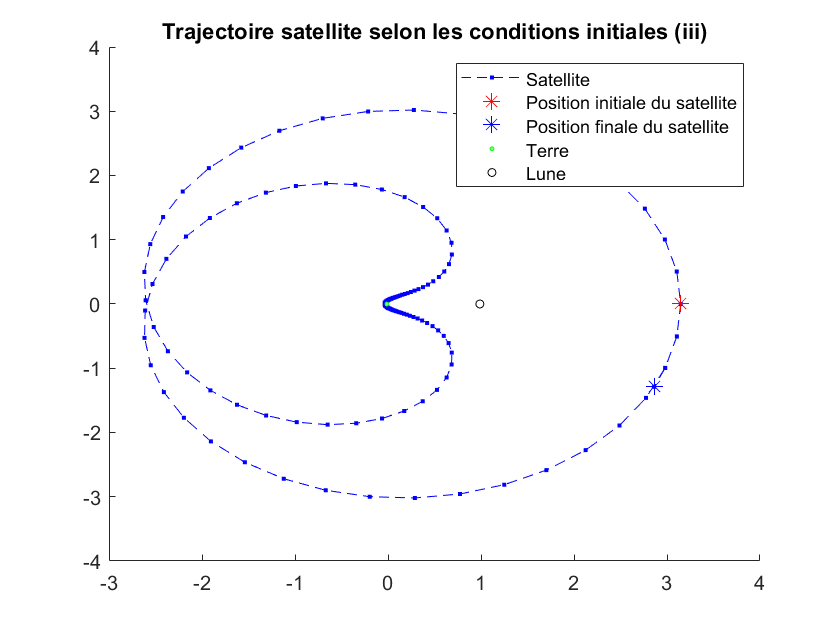

figure(3);
clf;
hold on;
plot(Z3(1,:),Z3(2,:),'b.--')
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z3(1,end),Z3(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',2,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (iii)')

#### (2.3.b) Trouver la période.

Z=Z3;      % Adapté selon la situation

listI = [0;0];      % Liste de l'index et du temps de partage
cand = z0;          % Liste de candidats passant par l'axe des x
candDist = z0-z0;   % Distance avec conditions initiales

for i=3:length(Z)
    yp = Z(2,i-1);
    yn = Z(2,i);
    if(yp*yn <= 0)
        % Noter l'index
        listI(:,end+1) = zeros(2,1);
        listI(1,end) = i;
        
        dist = abs(yp)/(abs(yp)+abs(yn));   % Distance par rapport à l'axe des x
        
        % Noter le temps de partage
        listI(2,end) = tList3(i-1) + dist*(tList3(i)-tList3(i-1));
        
        % Créer le candidat sur l'axe
        cand(:,end+1)  = zeros(4,1);
        cand(:,end) = Z(:,i-1) + dist*(Z(:,i)-Z(:,i-1));
        
        % Distance avec le vecteur de conditions initiales z0
        candDist(:,end+1) = cand(:,end)-z0;
       
    end
end

tolDist = 1e-1;         % Distance toléré avec les conditions initiales
for i =2:length(listI)
    if(norm(candDist(:,i)) < tolDist)
        T3 = listI(2,i)     % Break quand assez proche
        break;
    end
end

T3 =      1.256745073019388e+01

(2.2.c) RKF avec le $t_f =T_3$.

intervalle = [0,T3];
z0 = [3.147603117 ;0.0 ;0.0; -3.07676285];
[Z3,hList3,tList3] = rkf2023(@fTroisCorps,intervalle,z0,tol);
dFinRKF(3) = norm(Z3(:,end)-Z3(:,1));
N3 = length(hList3)

N3 =    144

Graphique de la trajectoire

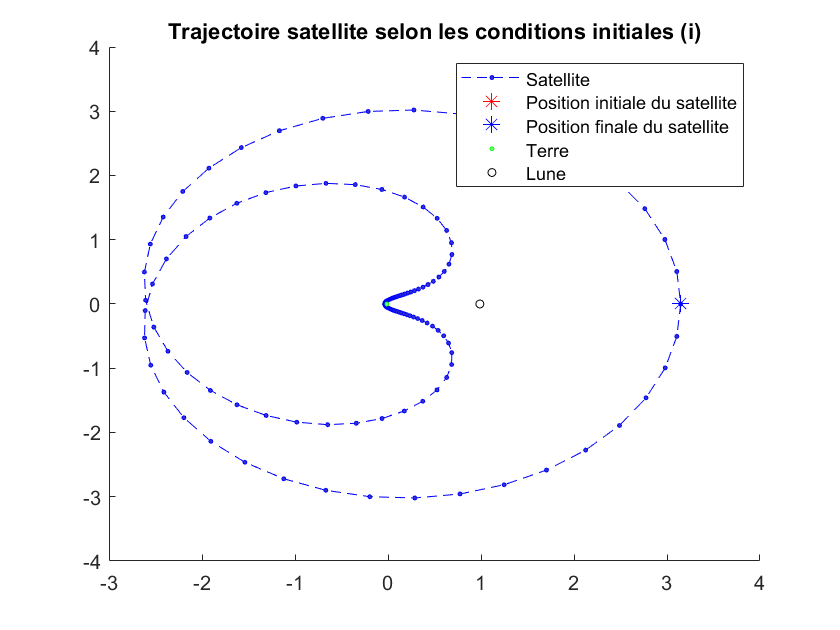

figure(1);
clf;
hold on;
plot(Z3(1,:),Z3(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z3(1,end),Z3(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',2,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (i)')

Graphique du pas de temps

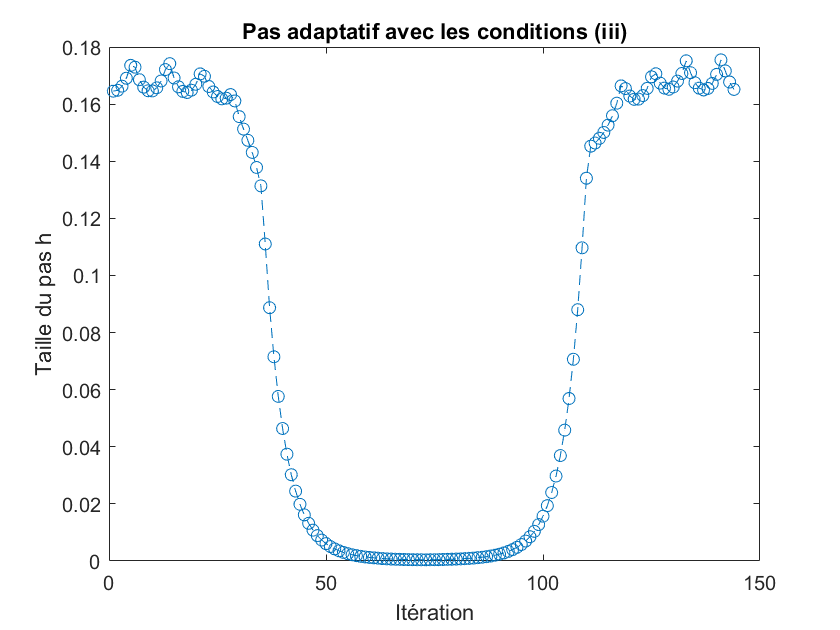

plot((1:length(hList3)),hList3,'o--')
xlabel('Itération')
ylabel('Taille du pas h')
title('Pas adaptatif avec les conditions (iii)')

Create GIF

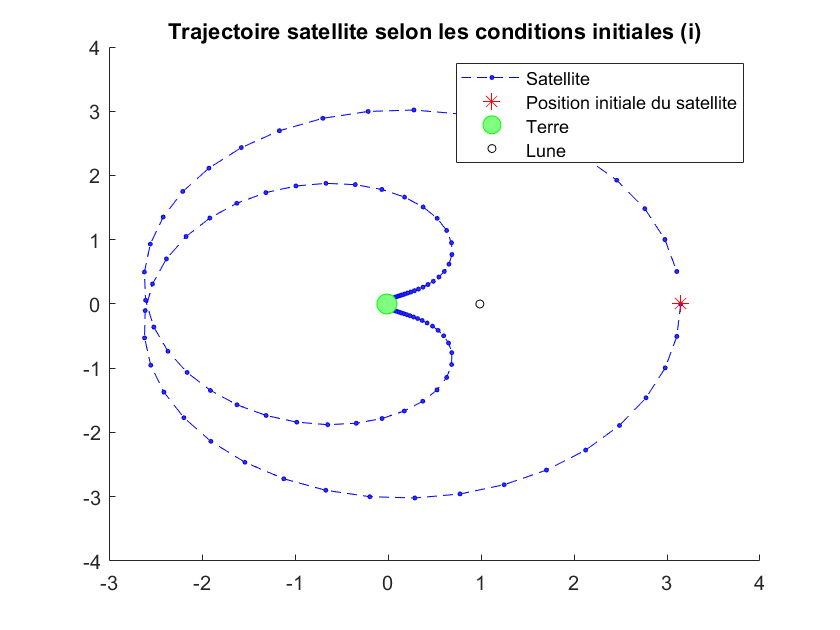

N = N3;
Z = Z3;
z0 = [-2.499999883 ;0.0 ;0.0; 2.100046263]; %Condition 1
z0 = [0.952281734 ;0.0 ;0.0; -0.957747254]; %Condition 2
z0 = [3.147603117 ;0.0 ;0.0; -3.07676285]; %Condition 3
clf;
h = figure('Name','Esssaiii');

% This ensures that getframe() returns a consistent size
%axis([-2.5 2 -2.5 2.5]) 
%axis([-1.5 1.5 -0.5 0.5])
axis([-3 4 -4 4])

%filename = 'C:\Users\mhadd\OneDrive\Documents\GitHub\Mat6470-Mat6473\TP2\anim3CorpsC1.gif';
%filename = 'C:\Users\mhadd\OneDrive\Documents\GitHub\Mat6470-Mat6473\TP2\anim3CorpsC2.gif';
filename = 'C:\Users\mhadd\OneDrive\Documents\GitHub\Mat6470-Mat6473\TP2\anim3CorpsC3.gif';

for i = 1:N
    
    hold on;
    plot(Z(1,1:i),Z(2,1:i),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
    plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
    plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
    plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
    legend('Satellite','Position initiale du satellite','Terre','Lune')
    title('Trajectoire satellite selon les conditions initiales (i)')


    hold off;
    drawnow
      frame = getframe(h);
      im = frame2im(frame);
      [imind,cm] = rgb2ind(im,256);
      if i == 1;
          imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
      else
          imwrite(imind,cm,filename,'gif','DelayTime',0.08,'WriteMode','append');
      end
end

## Question 4 - Avec RK4

### 4.1

intervalle = [0,T1];
z0 = [-2.499999883 ;0.0 ;0.0; 2.100046263];
[Z1,tList1] = rk42023(@fTroisCorps,intervalle,z0,N1);

h =      1.790957855774827e-01

dFinRK4(1) = norm(Z1(:,end)-Z1(:,1));

Graphique de la trajectoire

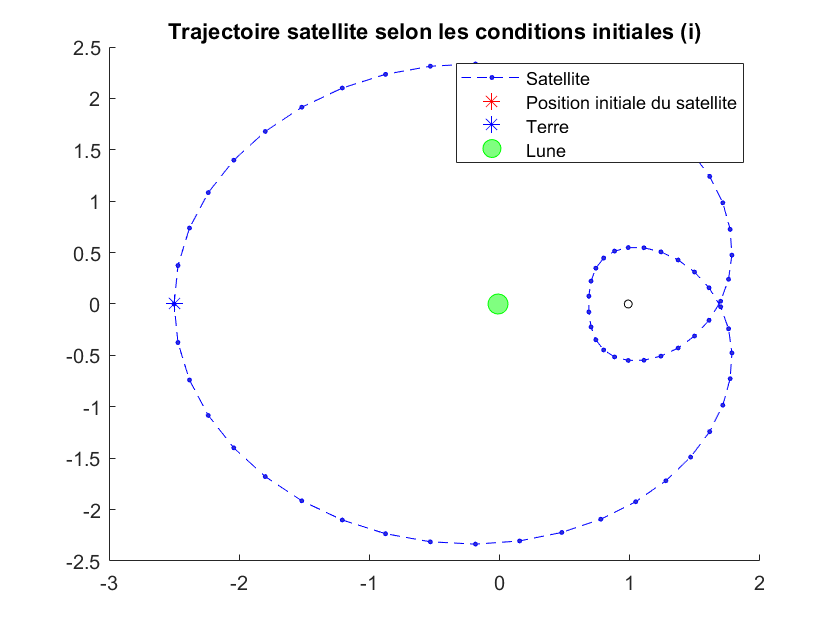

figure(1);
clf;
hold on;
plot(Z1(1,:),Z1(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z1(1,end),Z1(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (i)')

### 4.2

intervalle = [0,T2];
z0 = [0.952281734 ;0.0 ;0.0; -0.957747254];
[Z2,tList2] = rk42023(@fTroisCorps,intervalle,z0,N2);

h =      5.375407406121598e-02

dFinRK4(2) = norm(Z2(:,end)-Z2(:,1));

Graphique de la trajectoire

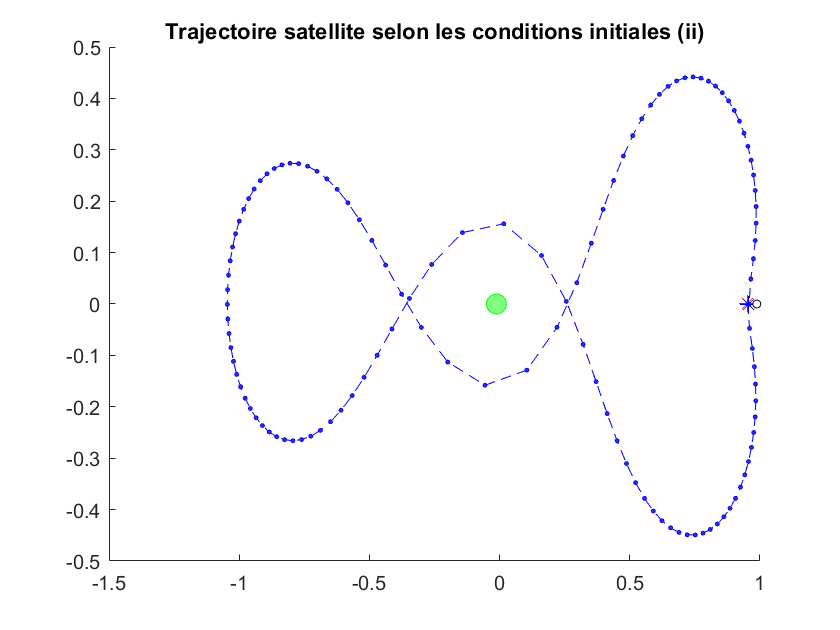

figure(1);
clf;
hold on;
plot(Z2(1,:),Z2(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z2(1,end),Z2(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
title('Trajectoire satellite selon les conditions initiales (ii)')

### 4.3

intervalle = [0,T3];
z0 = [3.147603117 ;0.0 ;0.0; -3.07676285];
[Z3,tList3] = rk42023(@fTroisCorps,intervalle,z0,N3);

h =      8.727396340412420e-02

dFinRK4(3) = norm(Z3(:,end)-Z3(:,1));

Graphique de la trajectoire

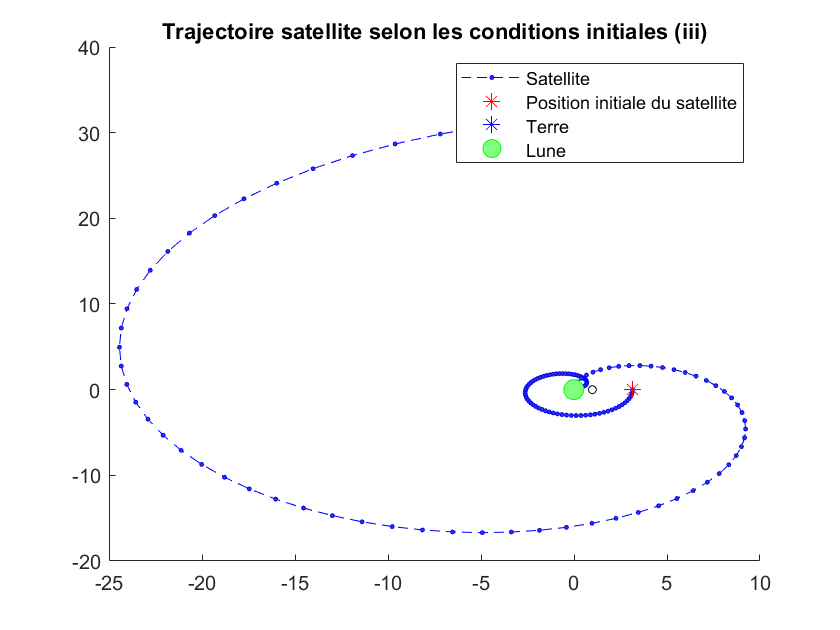

figure(1);
clf;
hold on;
plot(Z3(1,:),Z3(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(z0(1),z0(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Z3(1,end),Z3(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (iii)')

#### Comparaison entre RKF et RK4

dFinRK4 - dFinRKF

ans =      4.139225697621675e-04
     9.276309454717496e-02
     4.601051492217064e+01


## Question 5

Trois point d'équilibre

format long e;
intervalle = [0,60];
tolEq =1e-9;
pertur = [1e-6;1e-6;0;0];
pertur = [1e-6;1e-6;1e-6;1e-6];
xp1=fzero(@eq2TP2,-1.2)

xp1 =     -1.005064523363379e+00

xp2=fzero(@eq2TP2,0.5)

xp2 =      8.368929542662011e-01

xp3=fzero(@eq2TP2,1.2)

xp3 =      1.155699494873662e+00

p1 = [xp1;0;0;0];
p2 = [xp2;0;0;0];
p3 = [xp3;0;0;0];

### (5.a) Premier point

Zp1 = rkf2023(@fTroisCorps,intervalle,p1+pertur,tolEq);

Graphique de la trajectoire

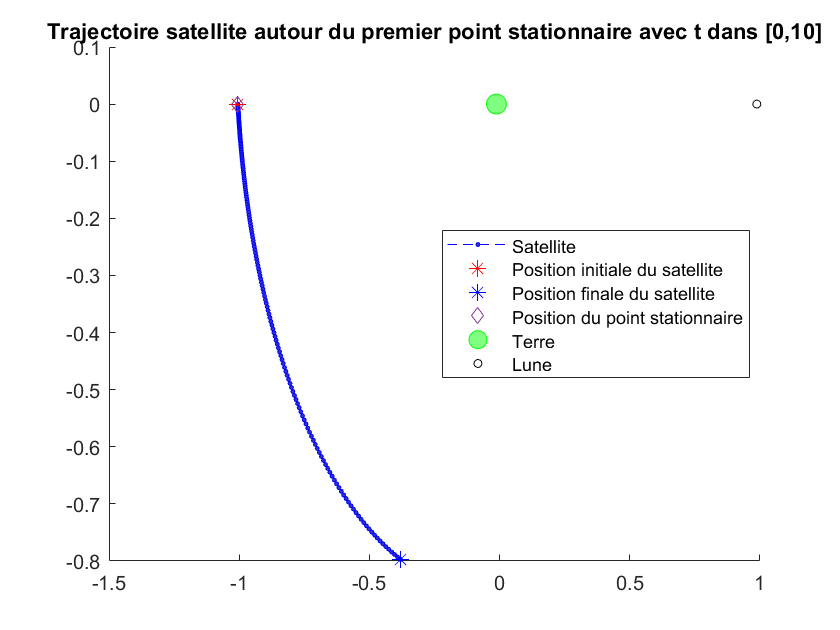

figure(1);
clf;
hold on;
plot(Zp1(1,:),Zp1(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(p1(1),p1(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Zp1(1,end),Zp1(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(p1(1)+pertur(1),p1(2)+pertur(1),'diamond','MarkerSize',6);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Position du point stationnaire','Terre','Lune',"Location",'best')
title('Trajectoire satellite autour du premier point stationnaire avec t dans [0,10]')

### (5.b) Deuxième point

intervalle = [0,10];
Zp2 = rkf2023(@fTroisCorps,intervalle,pertur+p2,tolEq);

Graphique de la trajectoire

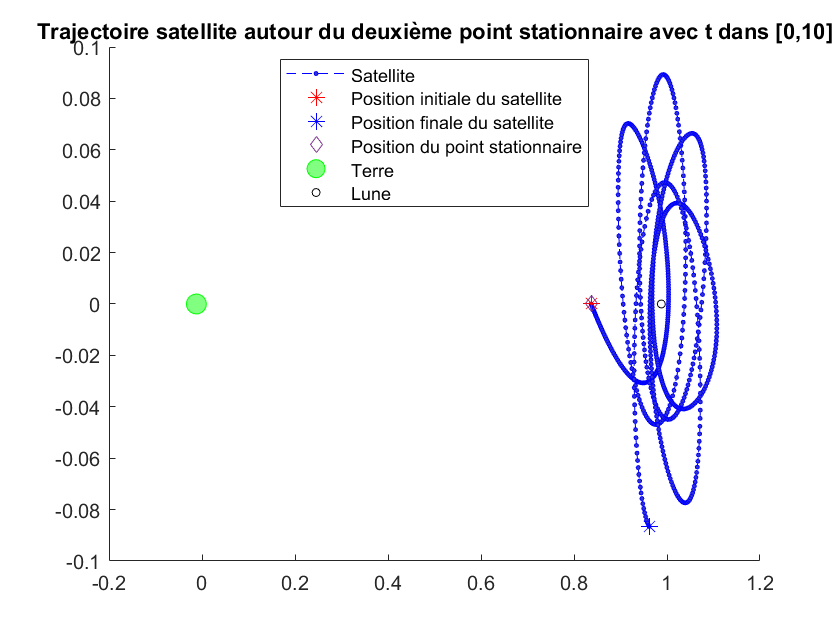

figure(1);
clf;
hold on;
plot(Zp2(1,:),Zp2(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(pertur(1)+p2(1),pertur(2)+p2(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Zp2(1,end),Zp2(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(p2(1),p2(2),'diamond','MarkerSize',6);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Position du point stationnaire','Terre','Lune',"Location",'best')
title('Trajectoire satellite autour du deuxième point stationnaire avec t dans [0,10]')

### (5.c) Troisième point

Zp3 = rkf2023(@fTroisCorps,intervalle,pertur+p3,tolEq);

Graphique de la trajectoire

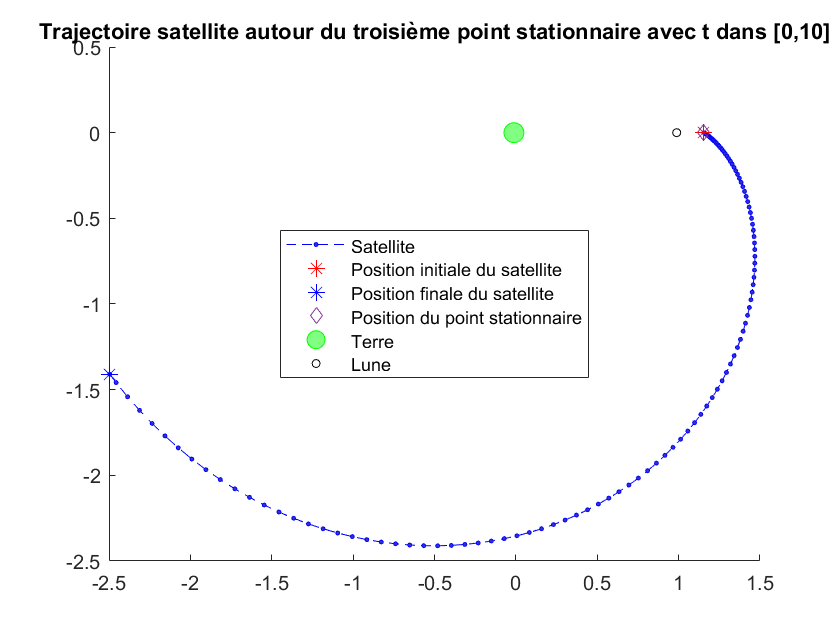

figure(1);
clf;
hold on;
plot(Zp3(1,:),Zp3(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(pertur(1)+p3(1),pertur(2)+p3(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Zp3(1,end),Zp3(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(p3(1),p3(2),'diamond','MarkerSize',6);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Position du point stationnaire','Terre','Lune',"Location",'best')
title('Trajectoire satellite autour du troisième point stationnaire avec t dans [0,10]')

### (5.d) Quatrième et cinquième point de stabilité

#### Quatrième point

intervalle = [0,40];
yp4 = sqrt(1-0.5^2);
xp4 = -mu+0.5;
p4 = [xp4;yp4;0;0];
Zp4 = rkf2023(@fTroisCorps,intervalle,pertur+p4,tolEq);

Graphique de la trajectoire

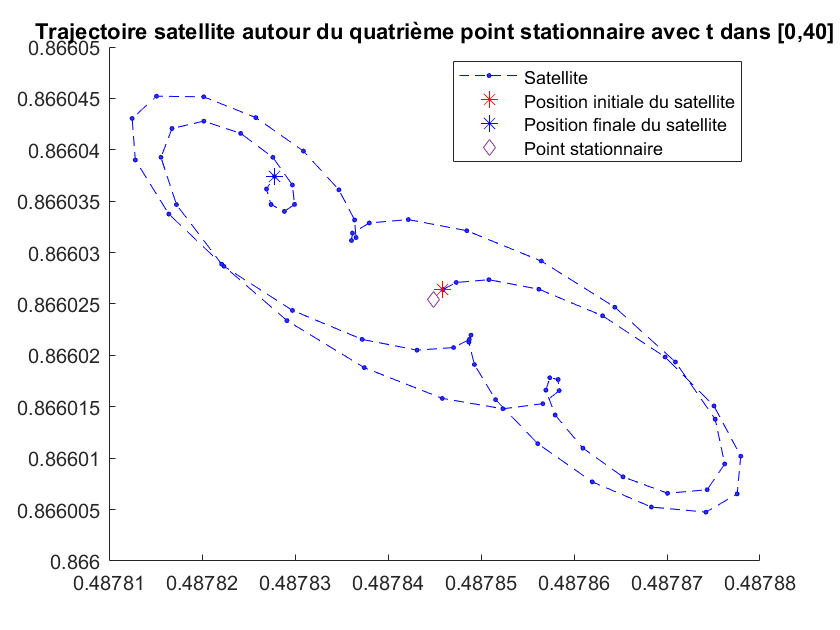

figure(1);
clf;
hold on;
plot(Zp4(1,:),Zp4(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(pertur(1)+p4(1),pertur(2)+p4(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Zp4(1,end),Zp4(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(p4(1),p4(2),'diamond','MarkerSize',6);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Point stationnaire',"Location",'best')
title('Trajectoire satellite autour du quatrième point stationnaire avec t dans [0,40]')

#### Cinquième point

intervalle = [0,40];
yp5 = -sqrt(1-0.5^2);
xp5 = -mu+0.5;
p5 = [xp5;yp5;0;0];
Zp5 = rkf2023(@fTroisCorps,intervalle,pertur+p5,tolEq);

Graphique de la trajectoire

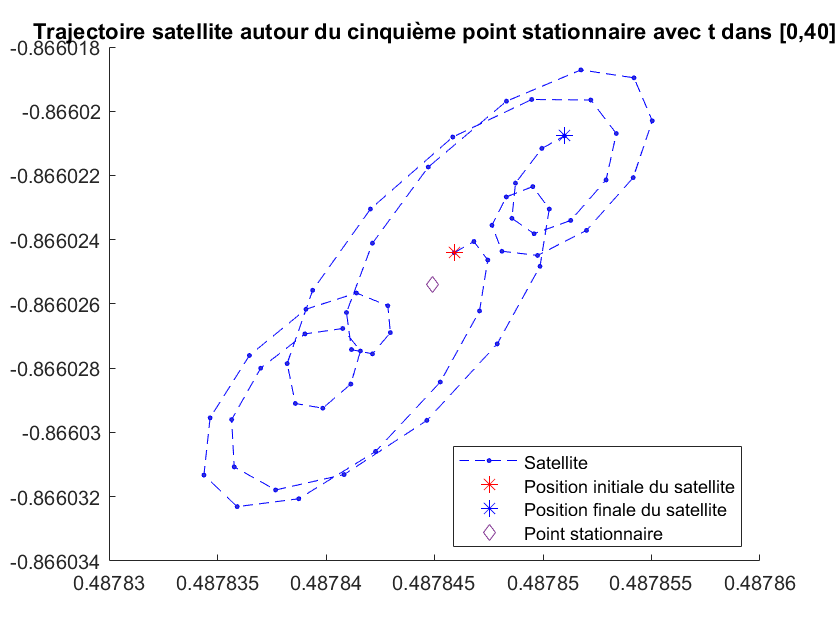

figure(1);
clf;
hold on;
plot(Zp5(1,:),Zp5(2,:),'b--o','MarkerSize',2,'MarkerFaceColor',[0.2,0.2,0.8])
plot(pertur(1)+p5(1),pertur(2)+p5(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(Zp5(1,end),Zp5(2,end),'b*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(p5(1),p5(2),'diamond','MarkerSize',6);
hold off;
legend('Satellite','Position initiale du satellite','Position finale du satellite','Point stationnaire',"Location",'best')
title('Trajectoire satellite autour du cinquième point stationnaire avec t dans [0,40]')

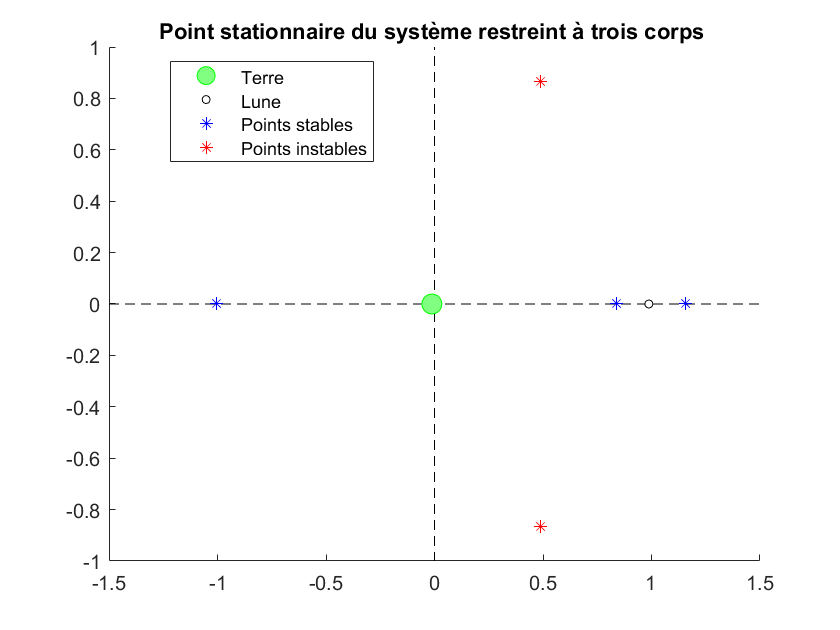

figure(1);
clf;
hold on;
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
plot([p1(1),p2(1),p3(1)],[p1(2),p2(2),p1(2)],'b*','MarkerSize',6);
plot([p4(1),p5(1)],[p4(2),p5(2)],'r*','MarkerSize',6);
plot([-1.5,1.5],[0,0],'k--','MarkerSize',6);
plot([0,0],[-1,1],'k--','MarkerSize',6);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
plot([p1(1),p2(1),p3(1)],[p1(2),p2(2),p1(2)],'b*','MarkerSize',6);
plot([p4(1),p5(1)],[p4(2),p5(2)],'r*','MarkerSize',6);
hold off;
legend('Terre','Lune','Points stables','Points instables',"Location",'best')
title('Point stationnaire du système restreint à trois corps ')

[p1,p2,p3,p4,p5]'

ans =     -1.005064523363379e+00                         0                         0                         0
     8.368929542662012e-01                         0                         0                         0
     1.155699494873662e+00                         0                         0                         0
     4.878449080000000e-01     8.660254037844386e-01                         0                         0
     4.878449080000000e-01    -8.660254037844386e-01                         0                         0
